clear all;
clf reset;

global colors;
colors = [
    [1, 1, 1]; ...
    [0.58, 0.79, 0.29]; ...
    [0.37, 0.60, 0.96]; ...
    [0.93, 0.56, 0.25]; ...
    [1, 0.88, 0.51]
];

level = 3;
differ_indicator = @(this, that) this == that;
%dist_evaluator = @(i, j) abs(i - j) / (level - 1);
dist_evaluator = @(i, j) 1;
prop = @(val, sim_arguments) val < 0.99 && abs(sim_arguments.thre - val) / sim_arguments.thre * rand() < 0.5;

global empty_as_unhappy;
empty_as_unhappy = false;

m = 50;
n = 50;

GBase = create_grid(m, n, [0.4, 0.5])

GBase =      2     2     0     1     0     2     1     1     2     0     0     1     0     0     2     2     1     2     0     2     0     2     1     2     0     2     2     2     1     2     1     2     1     1     1     1     2     2     1     0     1     2     1     2     2     1     2     2     2     2
     1     1     2     2     1     1     2     0     1     2     1     2     1     2     2     2     0     2     1     1     1     2     1     2     1     0     1     1     1     2     2     1     2     2     2     0     1     2     2     1     2     1     1     2     2     0     1     2     2     1
     1     1     2     1     2     1     2     1     2     2     2     2     1     1     0     1     2     2     0     1     2     1     0     1     2     2     2     1     1     1     2     2     0     1     1     1     1     2     2     2     1     2     2     1     2     1     1     1     1     1
     2     2     1     0     0     2     2     1     0     1     1     2     1     1     

sz = size(GBase);
assert(sz(1) == m && sz(2) == n, "Wrong Size");

# Schelling

sim_arguments = struct( ...
        'thre', 0.5, ...
        'indicator', differ_indicator, ...
        'evaluator', dist_evaluator, ...
        'diameter_i', 1, ...
        'diameter_j', 1, ...
        'level', 3, ...
        'possibility', prop, ...
        'happiness_threshold', 0.6, ...
        'satisfied_allowed_to_move', true ...
    );
G = GBase(:, :);
run_simulation(G, "meow", sim_arguments);

Generated Random Initial Grid: 
Initial Happiness: 


### Different vacant ratios

sim_arguments = struct( ...
        'thre', 0.6, ...
        'indicator', differ_indicator, ...
        'evaluator', dist_evaluator, ...
        'diameter_i', 1, ...
        'diameter_j', 1, ...
        'level', 3, ...
        'possibility', prop, ...
        'happiness_threshold', 0.6, ...
        'satisfied_allowed_to_move', true ...
    );

% vacant ratio 0.04
disp("Part-1-DVR-0.04");

Part-1-DVR-0.04


Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1672

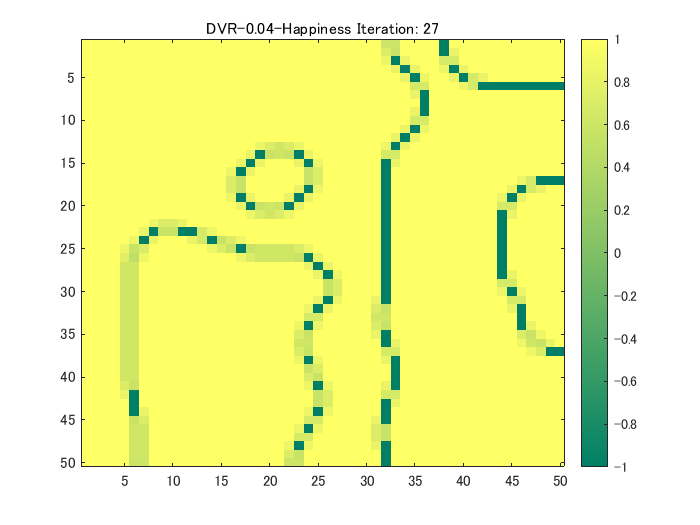

Iterations: 28
Final Unhappy Ratio: 
    0.0136



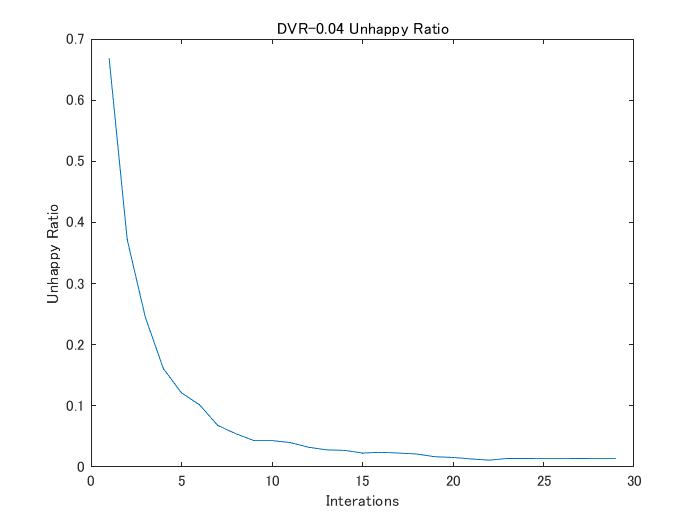

G = create_grid(50, 50, [0.48, 0.48]);
run_simulation(G, "DVR-0.04", sim_arguments);


% vacant ratio 0.06
disp("Part-1-DVR-0.06");

Part-1-DVR-0.06


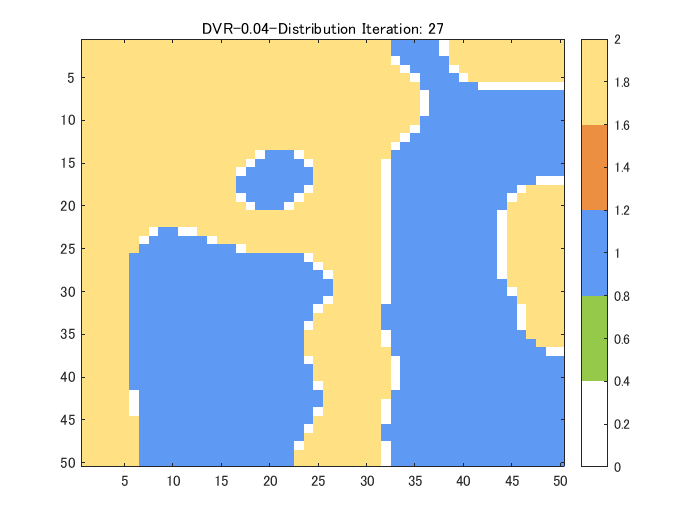

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1687

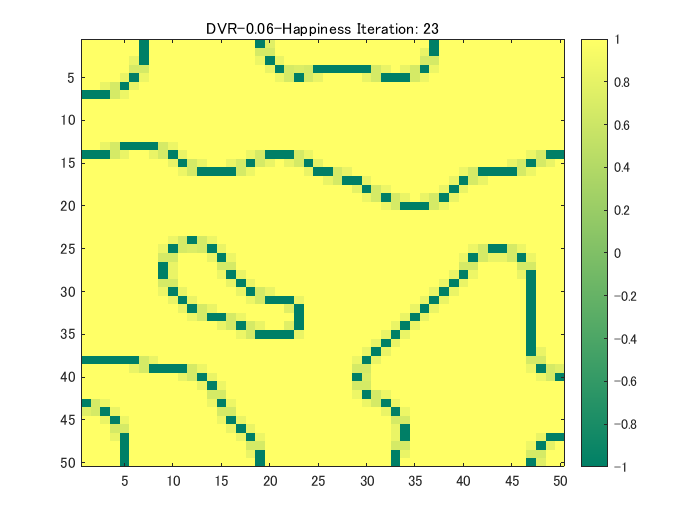

Iterations: 24
Final Unhappy Ratio: 
     0



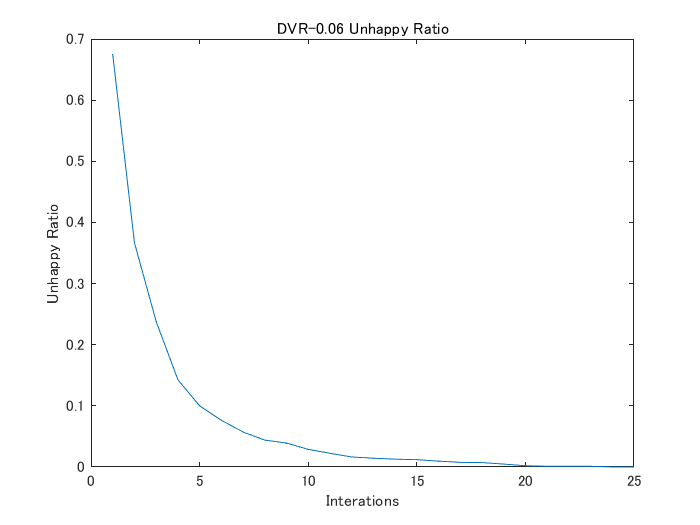

G = create_grid(50, 50, [0.47, 0.47]);
run_simulation(G, "DVR-0.06", sim_arguments);


% vacant ratio 0.10
disp("Part-1-DVR-0.10");

Part-1-DVR-0.10


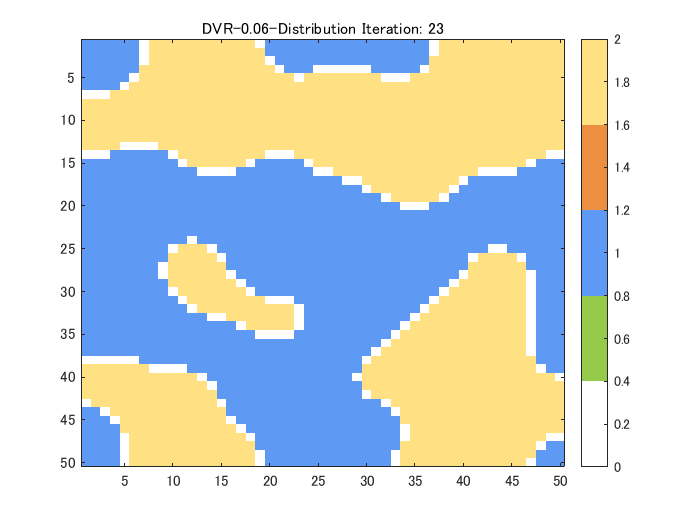

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1777

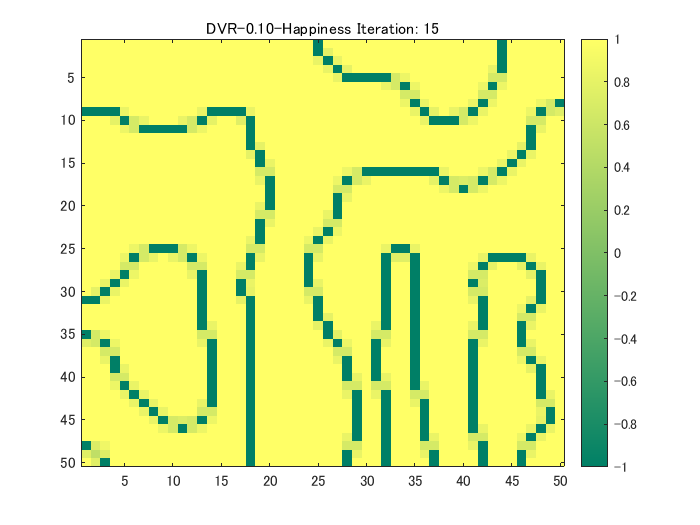

Iterations: 16
Final Unhappy Ratio: 
   4.0000e-04



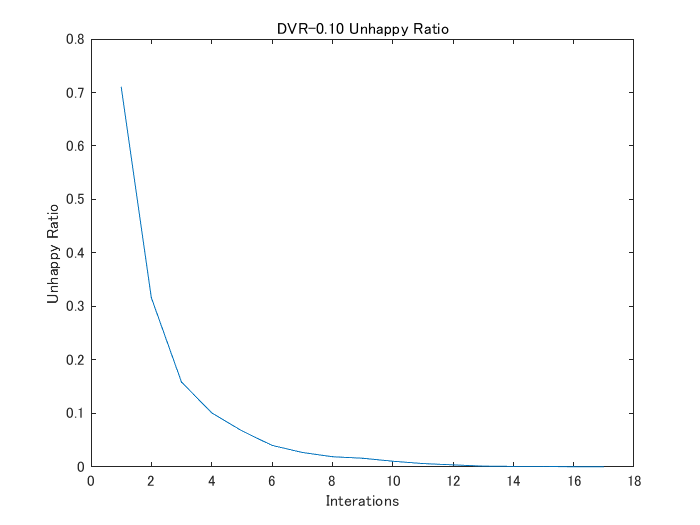

G = create_grid(50, 50, [0.45, 0.45]);
run_simulation(G, "DVR-0.10", sim_arguments);


% vacant ratio 0.16
disp("Part-1-DVR-0.16");

Part-1-DVR-0.16


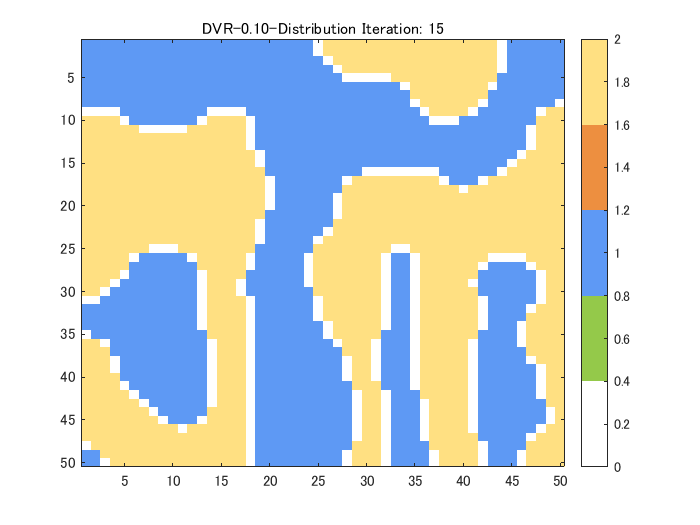

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1793

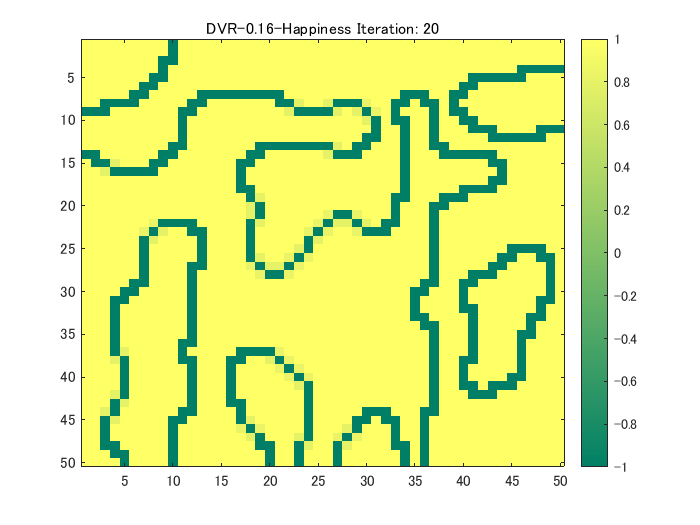

Iterations: 21
Final Unhappy Ratio: 
     0



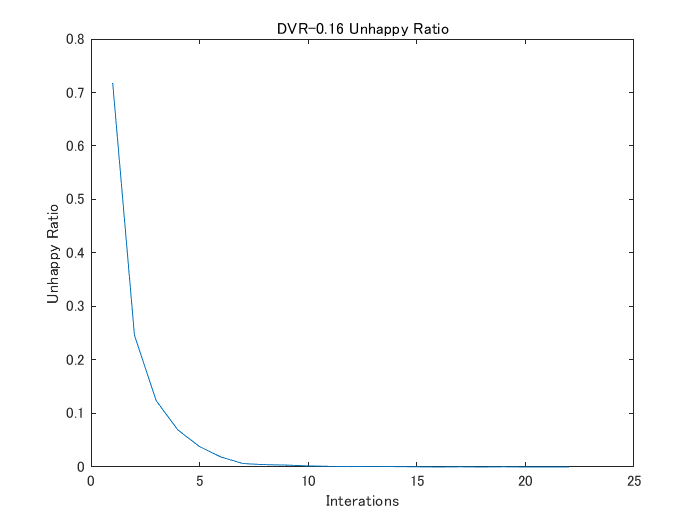

G = create_grid(50, 50, [0.42, 0.42]);
run_simulation(G, "DVR-0.16", sim_arguments);


% vacant ratio 0.32
disp("Part-1-DVR-0.32");

Part-1-DVR-0.32


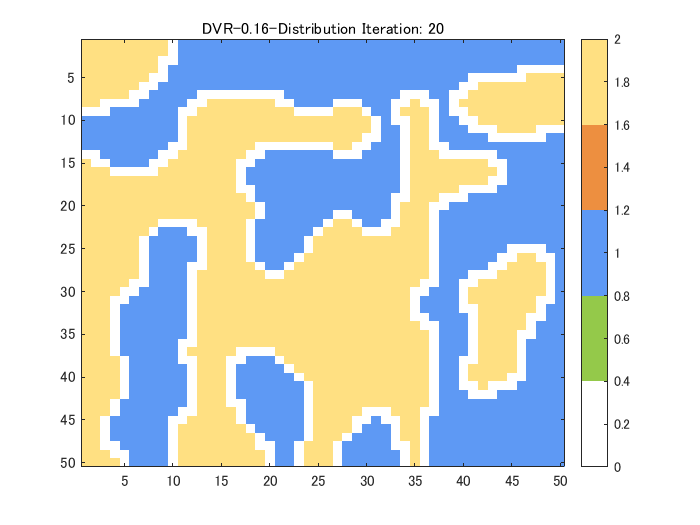

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1857

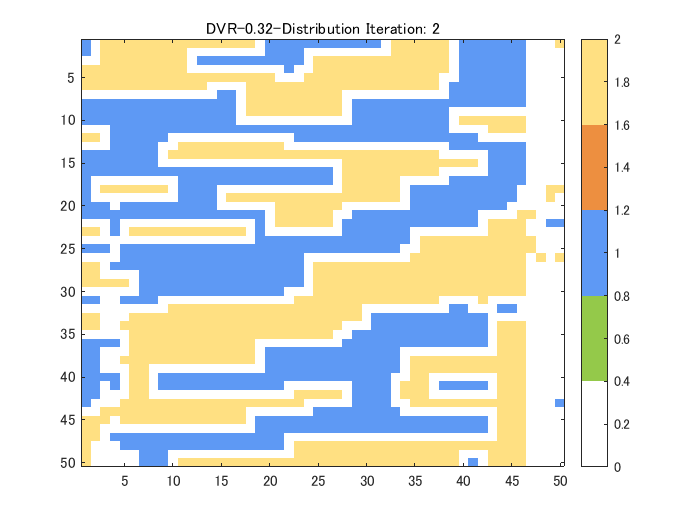

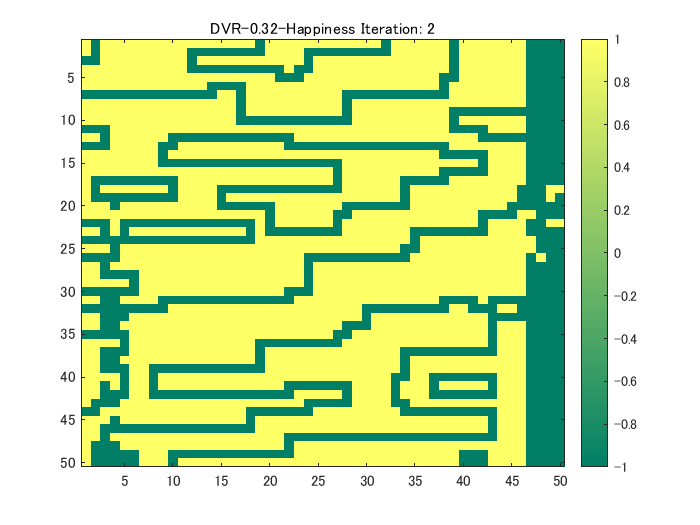

Iterations: 3
Final Unhappy Ratio: 
     0



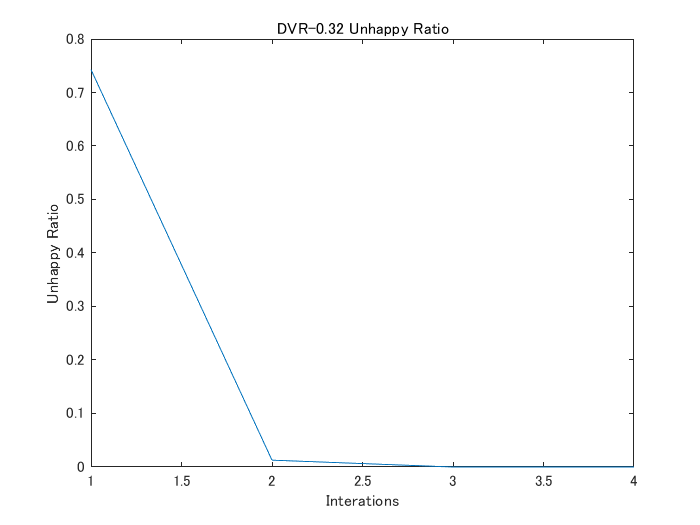

G = create_grid(50, 50, [0.34, 0.34]);
run_simulation(G, "DVR-0.32", sim_arguments);

### Satisfied (not) allowed to move

G = create_grid(50, 50, [0.45, 0.45]);
sim_arguments_allowed = struct( ...
        'thre', 0.6, ...
        'indicator', differ_indicator, ...
        'evaluator', dist_evaluator, ...
        'diameter_i', 1, ...
        'diameter_j', 1, ...
        'level', 3, ...
        'possibility', prop, ...
        'happiness_threshold', 0.6, ...
        'satisfied_allowed_to_move', true ...
    );
prop_not_allowed = @(val, sim_arguments) min(1, (sim_arguments.thre - val + 0.2) * rand()) * 1.5 > 0.5;
sim_arguments_notallowed = struct( ...
        'thre', 0.6, ...
        'indicator', differ_indicator, ...
        'evaluator', dist_evaluator, ...
        'diameter_i', 1, ...
        'diameter_j', 1, ...
        'level', 3, ...
        'possibility', prop_not_allowed, ...
        'happiness_threshold', 0.6, ...
        'satisfied_allowed_to_move', false ...
    );

% allowed
disp("Part-2-SAM-Allowed");

Part-2-SAM-Allowed


Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1778

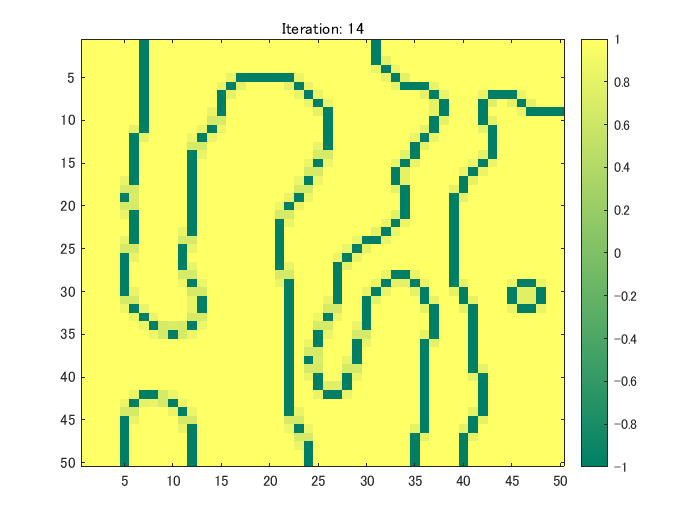

Iterations: 15
Final Unhappy Ratio: 
     0



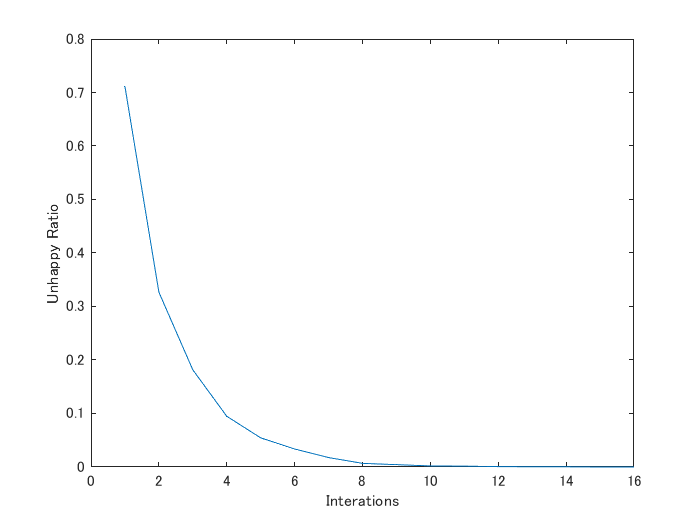

G1 = G(:, :);
run_simulation(G1, "SAM-Allowed", sim_arguments_allowed);


% not-allowed
disp("Part-2-SAM-Not-Allowed");

Part-2-SAM-Not-Allowed


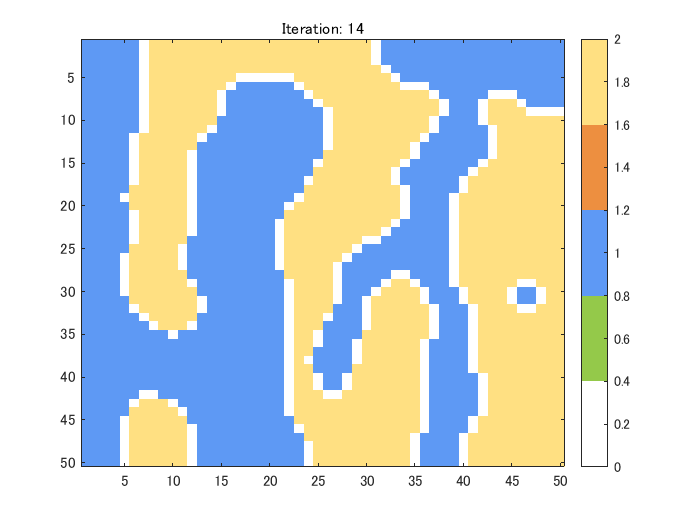

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1778

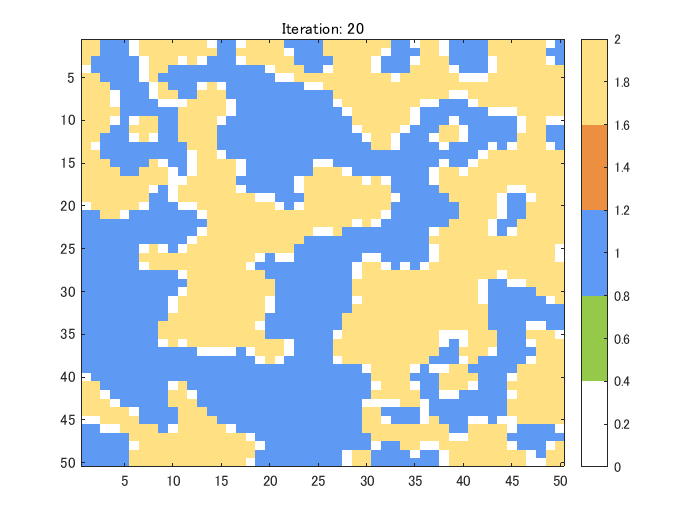

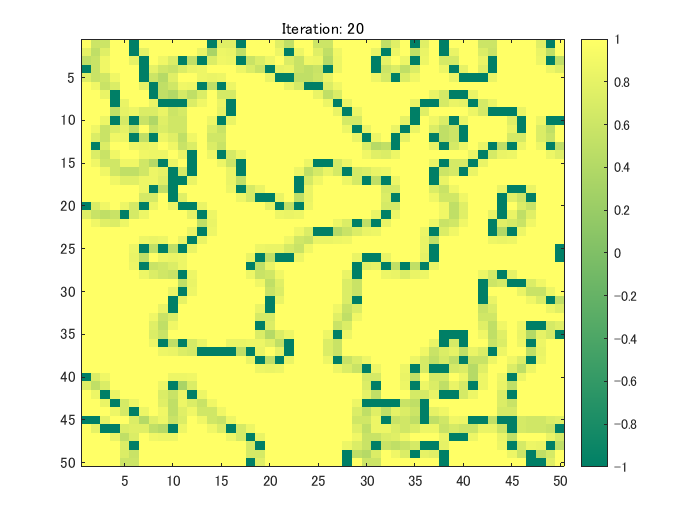

Iterations: 21
Final Unhappy Ratio: 
    0.0680



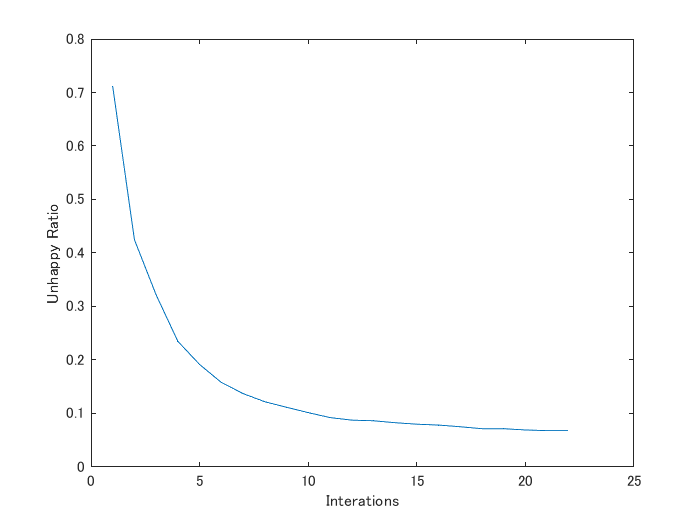

G2 = G(:, :);
run_simulation(G2, "SAM-Not-Allowed", sim_arguments_notallowed);

### Different thresholds

G = create_grid(50, 50, [0.47, 0.47]);
sim_arguments = struct( ...
        'thre', 0.26, ...
        'indicator', differ_indicator, ...
        'evaluator', dist_evaluator, ...
        'diameter_i', 1, ...
        'diameter_j', 1, ...
        'level', 3, ...
        'possibility', prop, ...
        'happiness_threshold', 0.26, ...
        'satisfied_allowed_to_move', true ...
    );

% 0.26
disp("Part-3-DT-0.26");

Part-3-DT-0.26


Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 426

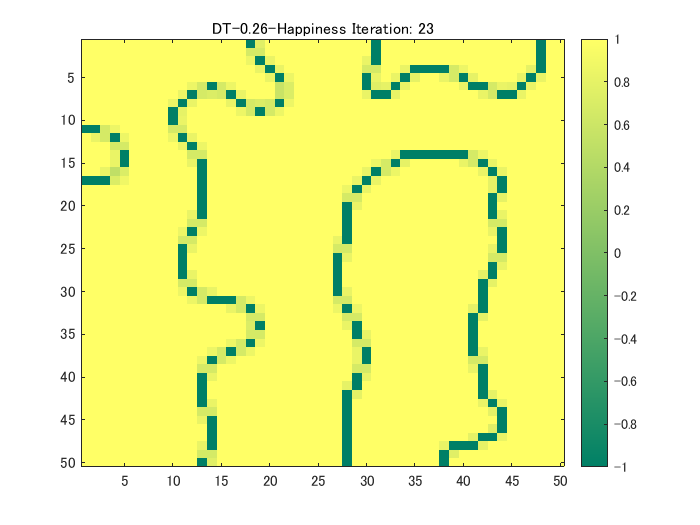

Iterations: 24
Final Unhappy Ratio: 
     0



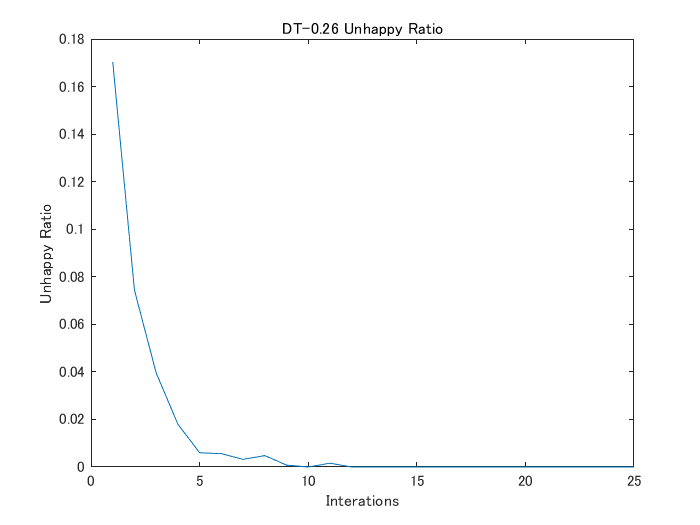

G1 = G(:, :);
run_simulation(G1, "DT-0.26", sim_arguments);


% 0.40
sim_arguments.thre = 0.40

sim_arguments = フィールドをもつ struct :
                         thre: 0.4000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.2600
    satisfied_allowed_to_move: 1


sim_arguments.happiness_threshold = 0.40

sim_arguments = フィールドをもつ struct :
                         thre: 0.4000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.4000
    satisfied_allowed_to_move: 1


disp("Part-3-DT-0.40");

Part-3-DT-0.40


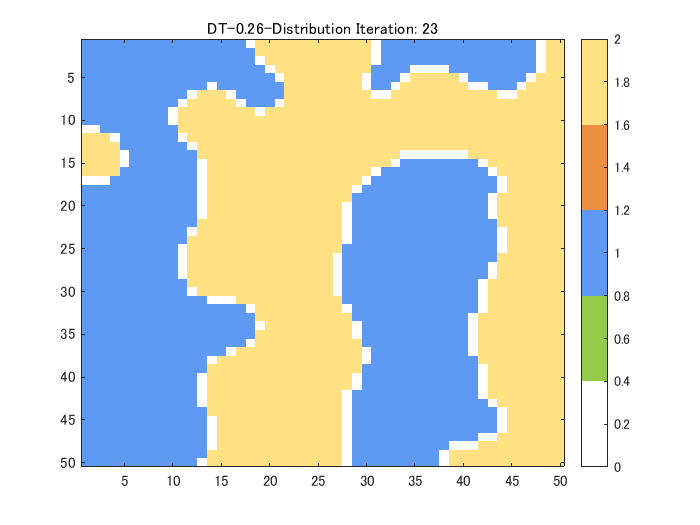

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 864

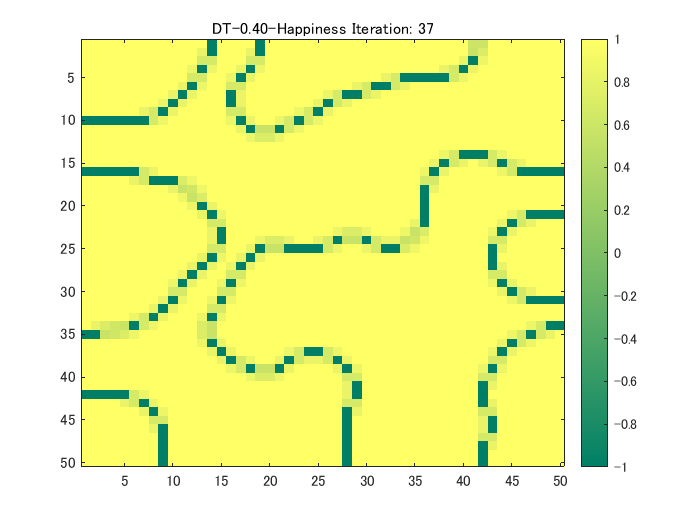

Iterations: 38
Final Unhappy Ratio: 
     0



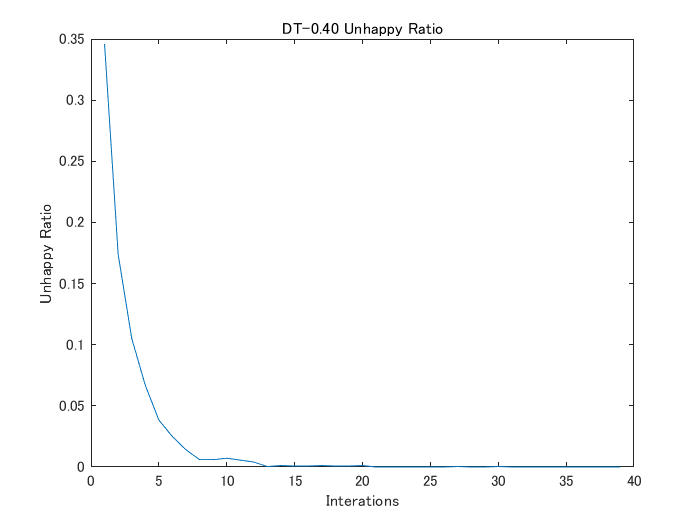

G2 = G(:, :);
run_simulation(G2, "DT-0.40", sim_arguments);


% 0.50
sim_arguments.thre = 0.50

sim_arguments = フィールドをもつ struct :
                         thre: 0.5000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.4000
    satisfied_allowed_to_move: 1


sim_arguments.happiness_threshold = 0.50

sim_arguments = フィールドをもつ struct :
                         thre: 0.5000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.5000
    satisfied_allowed_to_move: 1


disp("Part-3-DT-0.50");

Part-3-DT-0.50


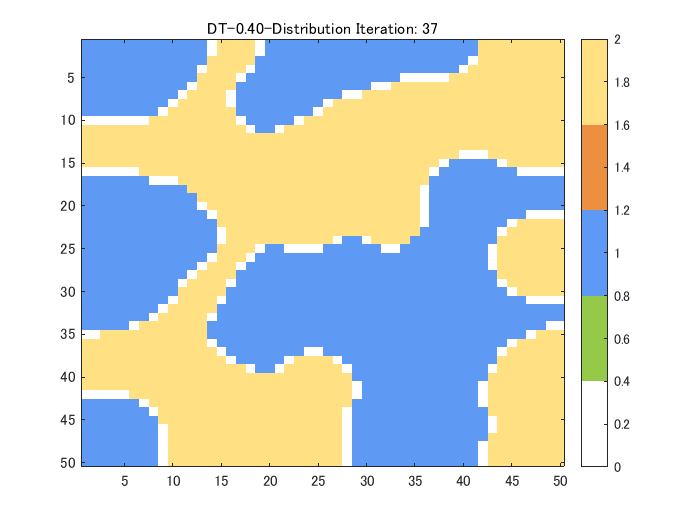

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 1069

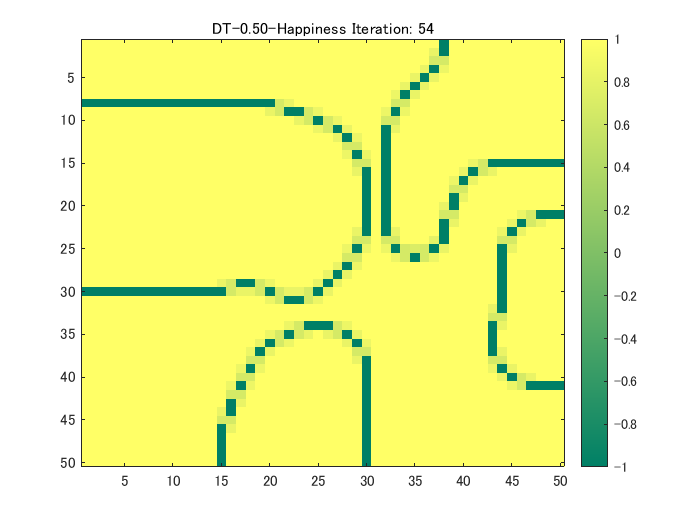

Iterations: 55
Final Unhappy Ratio: 
     0



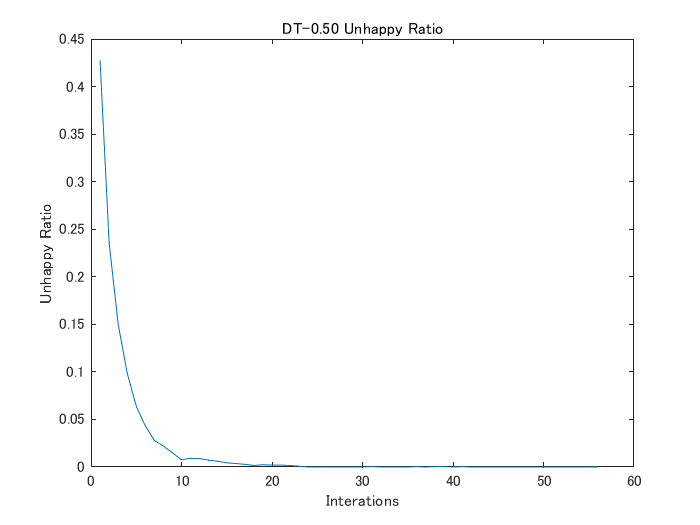

G3 = G(:, :);
run_simulation(G3, "DT-0.50", sim_arguments);


% 0.70
sim_arguments.thre = 0.70

sim_arguments = フィールドをもつ struct :
                         thre: 0.7000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.5000
    satisfied_allowed_to_move: 1


sim_arguments.happiness_threshold = 0.70

sim_arguments = フィールドをもつ struct :
                         thre: 0.7000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.7000
    satisfied_allowed_to_move: 1


disp("Part-3-DT-0.70");

Part-3-DT-0.70


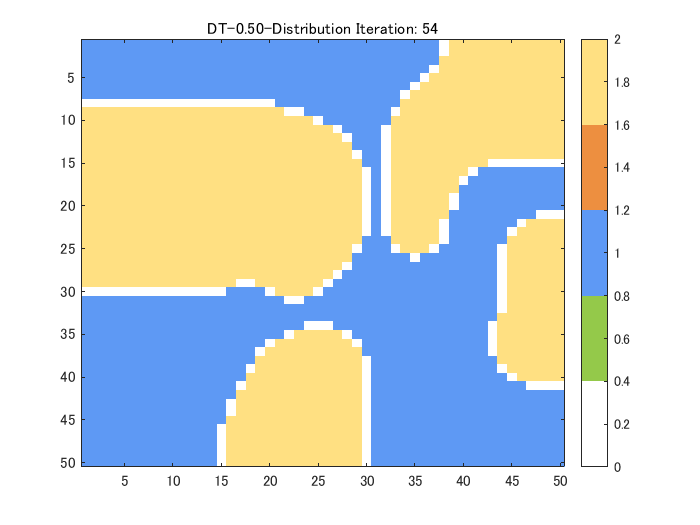

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 2101

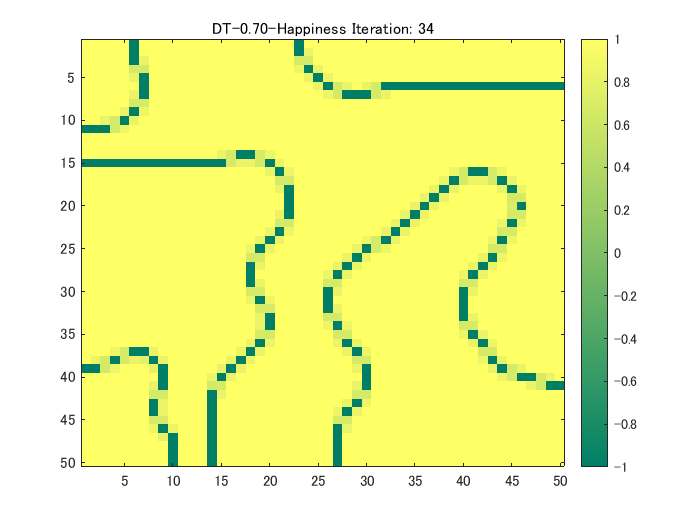

Iterations: 35
Final Unhappy Ratio: 
    0.0296



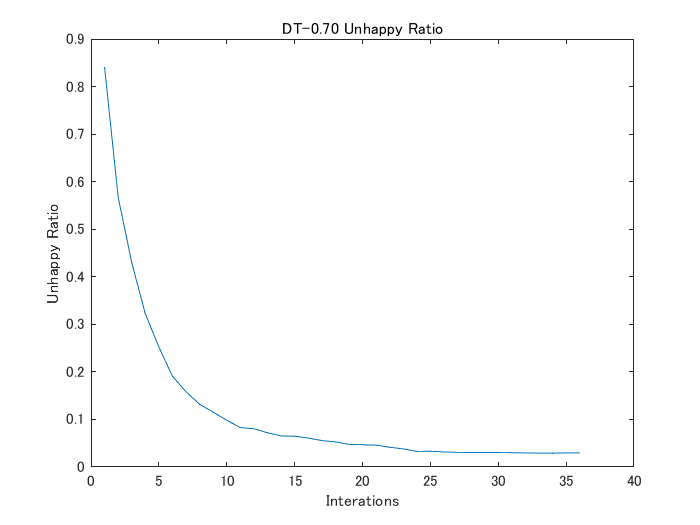

G4 = G(:, :);
run_simulation(G4, "DT-0.70", sim_arguments);


% 0.90
sim_arguments.thre = 0.90

sim_arguments = フィールドをもつ struct :
                         thre: 0.9000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.7000
    satisfied_allowed_to_move: 1


sim_arguments.happiness_threshold = 0.90

sim_arguments = フィールドをもつ struct :
                         thre: 0.9000
                    indicator: @(this,that)this==that
                    evaluator: @(i,j)1
                   diameter_i: 1
                   diameter_j: 1
                        level: 3
                  possibility: @(val,sim_arguments)val<0.99&&abs(sim_arguments.thre-val)/sim_arguments.thre*rand()<0.5
          happiness_threshold: 0.9000
    satisfied_allowed_to_move: 1


disp("Part-3-DT-0.90");

Part-3-DT-0.90


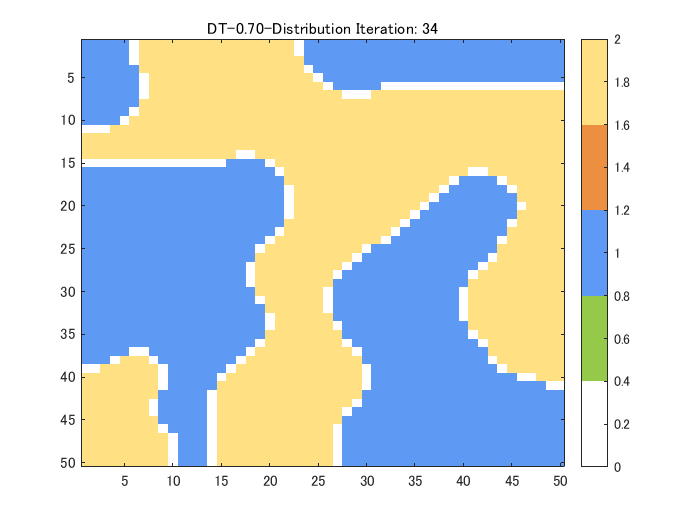

Generated Random Initial Grid: 
Initial Happiness: 


unhappiness = 2483

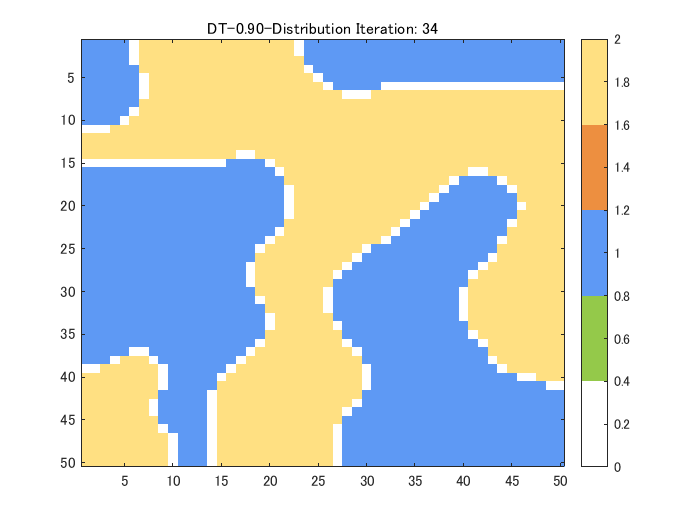

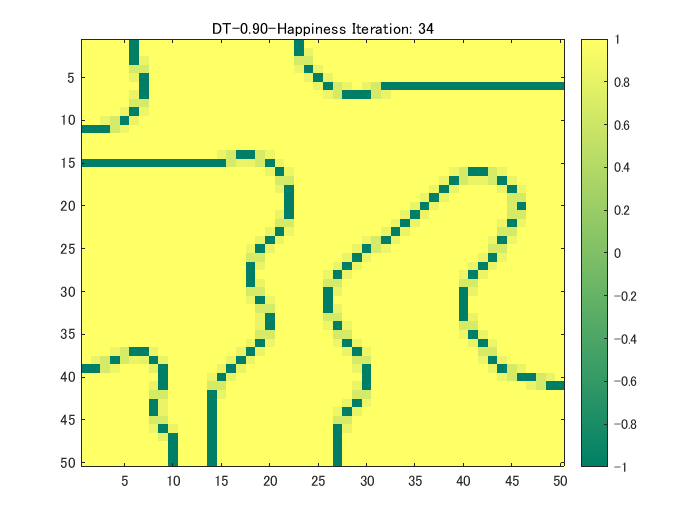

Iterations: 35
Final Unhappy Ratio: 
    0.0828



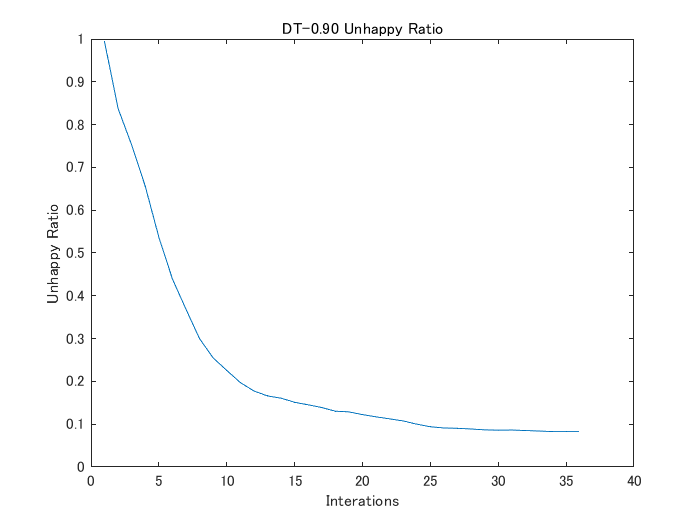

G5 = G(:, :);
run_simulation(G5, "DT-0.90", sim_arguments);

### Different possibility to move

G = create_grid(50, 50, [0.47, 0.47]);
sim_arguments = struct( ...
        'thre', 0.26, ...
        'indicator', differ_indicator, ...
        'evaluator', dist_evaluator, ...
        'diameter_i', 1, ...
        'diameter_j', 1, ...
        'level', 3, ...
        'possibility', prop, ...
        'happiness_threshold', 0.26, ...
        'satisfied_allowed_to_move', true ...
    );

% 0.26
disp("Part-3-DT-0.26");
G1 = G(:, :);
run_simulation(G1, "DT-0.26", sim_arguments);

% 0.40
sim_arguments.thre = 0.40
sim_arguments.happiness_threshold = 0.40
disp("Part-3-DT-0.40");
G2 = G(:, :);
run_simulation(G2, "DT-0.40", sim_arguments);

% 0.50
sim_arguments.thre = 0.50
sim_arguments.happiness_threshold = 0.50
disp("Part-3-DT-0.50");
G3 = G(:, :);
run_simulation(G3, "DT-0.50", sim_arguments);

% 0.70
sim_arguments.thre = 0.70
sim_arguments.happiness_threshold = 0.70
disp("Part-3-DT-0.70");
G4 = G(:, :);
run_simulation(G4, "DT-0.70", sim_arguments);

% 0.90
sim_arguments.thre = 0.90
sim_arguments.happiness_threshold = 0.90
disp("Part-3-DT-0.90");
G5 = G(:, :);
run_simulation(G5, "DT-0.90", sim_arguments);

## People want to be in higher class

differ_indicator = @(this, that) this <= that;

G = create_grid(100, 100, [0.2, 0.2, 0.2, 0.3]);
sim_arguments = struct( ...
        'thre', 0.5, ...
        'indicator', differ_indicator, ...
        'evaluator', dist_evaluator, ...
        'diameter_i', 1, ...
        'diameter_j', 1, ...
        'level', 5, ...
        'possibility', prop, ...
        'happiness_threshold', 0.5, ...
        'satisfied_allowed_to_move', true ...
    );

disp("Part-3-DT-0.6");

Part-3-DT-0.6


colors = parula(50);
run_simulation(G, "CLS-0.6", sim_arguments);

Generated Random Initial Grid: 


Initial Happiness: 


unhappiness = 3951

# Simulation

function run_simulation(G, fileprefix, sim_arguments) 
    global colors;
    k = 0;
    max_ite = 100;
    
    figure(1);
    axis tight manual
    
    disp("Generated Random Initial Grid: ")
    im = imagesc(G);
    colormap(colors);
    colorbar;
    title(fileprefix + "-Distribution Iteration: " + k)
    
    drawnow
    
    [AG, mapG] = rgb2ind(frame2im(getframe(1)), 256);
    imwrite(AG, mapG, fileprefix + "-G.gif", "gif");
    
    
    figure(2);
    
    S = calculate_happiness_matrix(G, sim_arguments);
    disp("Initial Happiness: ")
    im = imagesc(S);
    colormap summer;
    colorbar;
    title(fileprefix + "-Happiness Iteration: " + k)
    
    [AS, mapS] = rgb2ind(frame2im(getframe(2)), 256);
    imwrite(AS, mapS, fileprefix + "-S.gif", "gif");
    
    unhappiness = [length(find(S < sim_arguments.thre))]
    
    while k < max_ite
        k = k + 1;
    
        [G, S, updated, U] = advance_grid(G, S, sim_arguments.thre, sim_arguments.possibility, sim_arguments, 1);
        unhappiness = [unhappiness length(U)];
        if updated == false
            break;
        end
    
        % write G
        figure(1);
        imagesc(G);
        colormap(colors);
        colorbar;
        title(fileprefix + "-Distribution Iteration: " + k);
    
        [AG, mapG] = rgb2ind(frame2im(getframe(1)), 256);
        imwrite(AG, mapG, fileprefix + "-G.gif", "gif", "WriteMode", "append", "DelayTime", 0.5);
    
        % write S
        figure(2);
        imagesc(S);
        colormap summer;
        colorbar;
        title(fileprefix + "-Happiness Iteration: " + k);
    
        [AS, mapS] = rgb2ind(frame2im(getframe(2)), 256);
        imwrite(AS, mapS, fileprefix + "-S.gif", "gif", "WriteMode", "append", "DelayTime", 0.5);
    end
    
    disp("Iterations: " + k);
    
    sz = size(G);
    
    figure(3)
    plot(unhappiness / (sz(1) * sz(2)))
    xlabel("Interations")
    ylabel("Unhappy Ratio")
    title(fileprefix + " Unhappy Ratio")
    
    disp("Final Unhappy Ratio: ")
    disp(unhappiness(end) / (sz(1) * sz(2)));
    
    [AS, mapS] = rgb2ind(frame2im(getframe(3)), 256);
    imwrite(AS, mapS, fileprefix + "-UR.gif", "png");
end

micro motives need not to be equal to mircro behavior

# Additional Functions

#### Create Grid

function G = create_grid(m, n, ratios)
    G = zeros(m, n);

    cnts = floor(m * n * ratios);
    total = sum(cnts);
    
    %pool = [randi([1, m], total, 1) randi([1, n], total * 2, 1)];
    indices = randperm(m * n);
    indices = indices(1: total);
    coords = zeros(total, 2);
    for k = 1: length(indices)
        coords(k, :) = [fix((indices(k) - 1) / n) + 1, rem(indices(k), n) + 1];
    end
    ind = 1;
    for i = 1: length(cnts)
        for j = 1 : cnts(i)
            nxt = coords(ind, :);
            ind = ind + 1;
            G(nxt(1), nxt(2)) = i;
        end
    end
end

#### Draw Grid

#### Calculate Happiness

function happiness = calculate_happiness(mat, i, j, sim_arguments, ref)
    arguments
        mat
        i
        j
        sim_arguments
        ref = mat(i, j)
    end
    global empty_as_unhappy;

    happiness = -1;
    if ref == 0
        return
    end

    tmp = mat(i, j);
    mat(i, j) = ref;

    sz = size(mat);
    neibors = reshape(mat( ...
        max(1, i - sim_arguments.diameter_i) : min(sz(1), i + sim_arguments.diameter_i), ...
        max(1, j - sim_arguments.diameter_j) : min(sz(2), j + sim_arguments.diameter_j) ...
        ), 1, []);
    
    counts = zeros(sim_arguments.level, 1);
    for e = neibors
        %if e == 0
        %    continue;
        %end
        counts(e + 1) = counts(e + 1) + 1;
    end
    counts(ref + 1) = counts(ref + 1) - 1;

    mat(i, j) = tmp;

    happy = 0;
    nonhappy = 0;
    for i = 1 : length(counts)
        dist = sim_arguments.evaluator(ref, i - 1);
        if sim_arguments.indicator(ref, i - 1)
            happy = happy + counts(i) * dist;
        else
            if empty_as_unhappy == false && i == 1
                continue;
            end
            nonhappy = nonhappy + counts(i) * dist;
        end
    end
    if happy + nonhappy > 0
        happiness = happy / (happy + nonhappy);
    end
end

function S = calculate_happiness_matrix(G, sim_arguments)
    arguments
        G
        sim_arguments
    end

    sz = size(G);
    S = -ones(size(G));

    for i = 1 : sz(1)
        for j = 1 : sz(2)
            S(i, j) = calculate_happiness(G, i, j, sim_arguments);
        end
    end
end

Advance Grid

function [G, S, updated, unhappies] = advance_grid(G, S, trshd, prob, sim_arguments, mode) 
    arguments
        G
        S
        trshd
        prob
        sim_arguments
        mode
    end
    % mode - 1 : max happiness location
    sz = size(G);
    updated = false;
    if sim_arguments.satisfied_allowed_to_move
        agents = find(S > -0.5)';
        for agent = agents
            [real_i, real_j] = get_loc(G, agent);
            will_move = prob(S(real_i, real_j), sim_arguments);
            if S(real_i, real_j) >= trshd && will_move ~= true
                continue;
            end
            
            if mode == 1
                [new_i, new_j] = reallocate_max_hapiness(G, S, real_i, real_j, sim_arguments);
            elseif mode == 2
                [new_i, new_j] = reallocate_normal(G, S, real_i, real_j, sim_arguments);
            end
    
            if real_i ~= new_i && real_j ~= new_j
                old_val = G(real_i, real_j);
                G(real_i, real_j) = 0;
                G(new_i, new_j) = old_val;
                updated = true;
            end
        end
    else
        unhappies = find(S > -0.5 & S < trshd)';
        for unhappy = unhappies
            [real_i, real_j] = get_loc(G, unhappy);
            will_move = prob(S(real_i, real_j), sim_arguments);
            if will_move ~= true
                continue;
            end
            
            if mode == 1
                [new_i, new_j] = reallocate_max_hapiness(G, S, real_i, real_j, sim_arguments);
            elseif mode == 2
                [new_i, new_j] = reallocate_normal(G, S, real_i, real_j, sim_arguments);
            end
    
            if real_i ~= new_i && real_j ~= new_j
                old_val = G(real_i, real_j);
                G(real_i, real_j) = 0;
                G(new_i, new_j) = old_val;
                updated = true;
            end
        end
    end

    S = calculate_happiness_matrix(G, sim_arguments);
    unhappies = find(S > -0.5 & S < trshd)';
end

Get 2D indices from 1D indices

function [i, j] = get_loc(mat, ind)
    sz = size(mat);
    i = mod(ind, sz(1));
    if i == 0
        i = sz(1);
    end
    j = max(1, fix((ind - 1) / sz(1)) + 1);
end

# Reallocate Methods

Modified Reallocation - move to the place that can provide more happiness

function [new_i, new_j] = reallocate_max_hapiness(G, S, i, j, sim_arguments)
    arguments
        G
        S
        i
        j
        sim_arguments
    end
    
    new_i = i;
    new_j = j;
    empties = find(G == 0)';
    this_happiness = S(i, j);
    for empty = empties
        [that_i, that_j] = get_loc(G, empty);
        that_happiness = calculate_happiness(G, that_i, that_j, sim_arguments, G(i, j));
        if (that_happiness > this_happiness) 
            new_i = that_i;
            new_j = that_j;
            this_happiness = that_happiness;
        end
    end
end

Basic Reallocation - move to a place that can provide happiness above a threshold

function [new_i, new_j] = reallocate_normal(G, S, i, j, sim_arguments)
    arguments
        G
        S
        i
        j
        sim_arguments
    end
    
    new_i = i;
    new_j = j;
    empties = find(G == 0)';
    for empty = empties
        [that_i, that_j] = get_loc(G, empty);
        that_happiness = calculate_happiness(G, that_i, that_j, sim_arguments, G(i, j));
        if (that_happiness > sim_arguments.happiness_threshold) 
            new_i = that_i;
            new_j = that_j;
            break;
        end
    end
end